# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SR6.mat'
sr = sr6;

sr.homeConfig();
q_0 = sr.q;
q_dot_0 = sr.q_dot;

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
fx = 0;
fy = 0;
fz = 0;

nx = 0;
ny = 0;
nz = 0;

tau1 = 1;
tau2 = -1.5;
tau3 = -0.5;
tau4 = 0;
tau5 = 0;
tau6 = 1;

tau = [tau1; tau2; tau3; tau4; tau5; tau6];

### Launch Simulation

% profile on
tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 4.248632 seconds.


% profile viewer
% profile off

### Animate Results

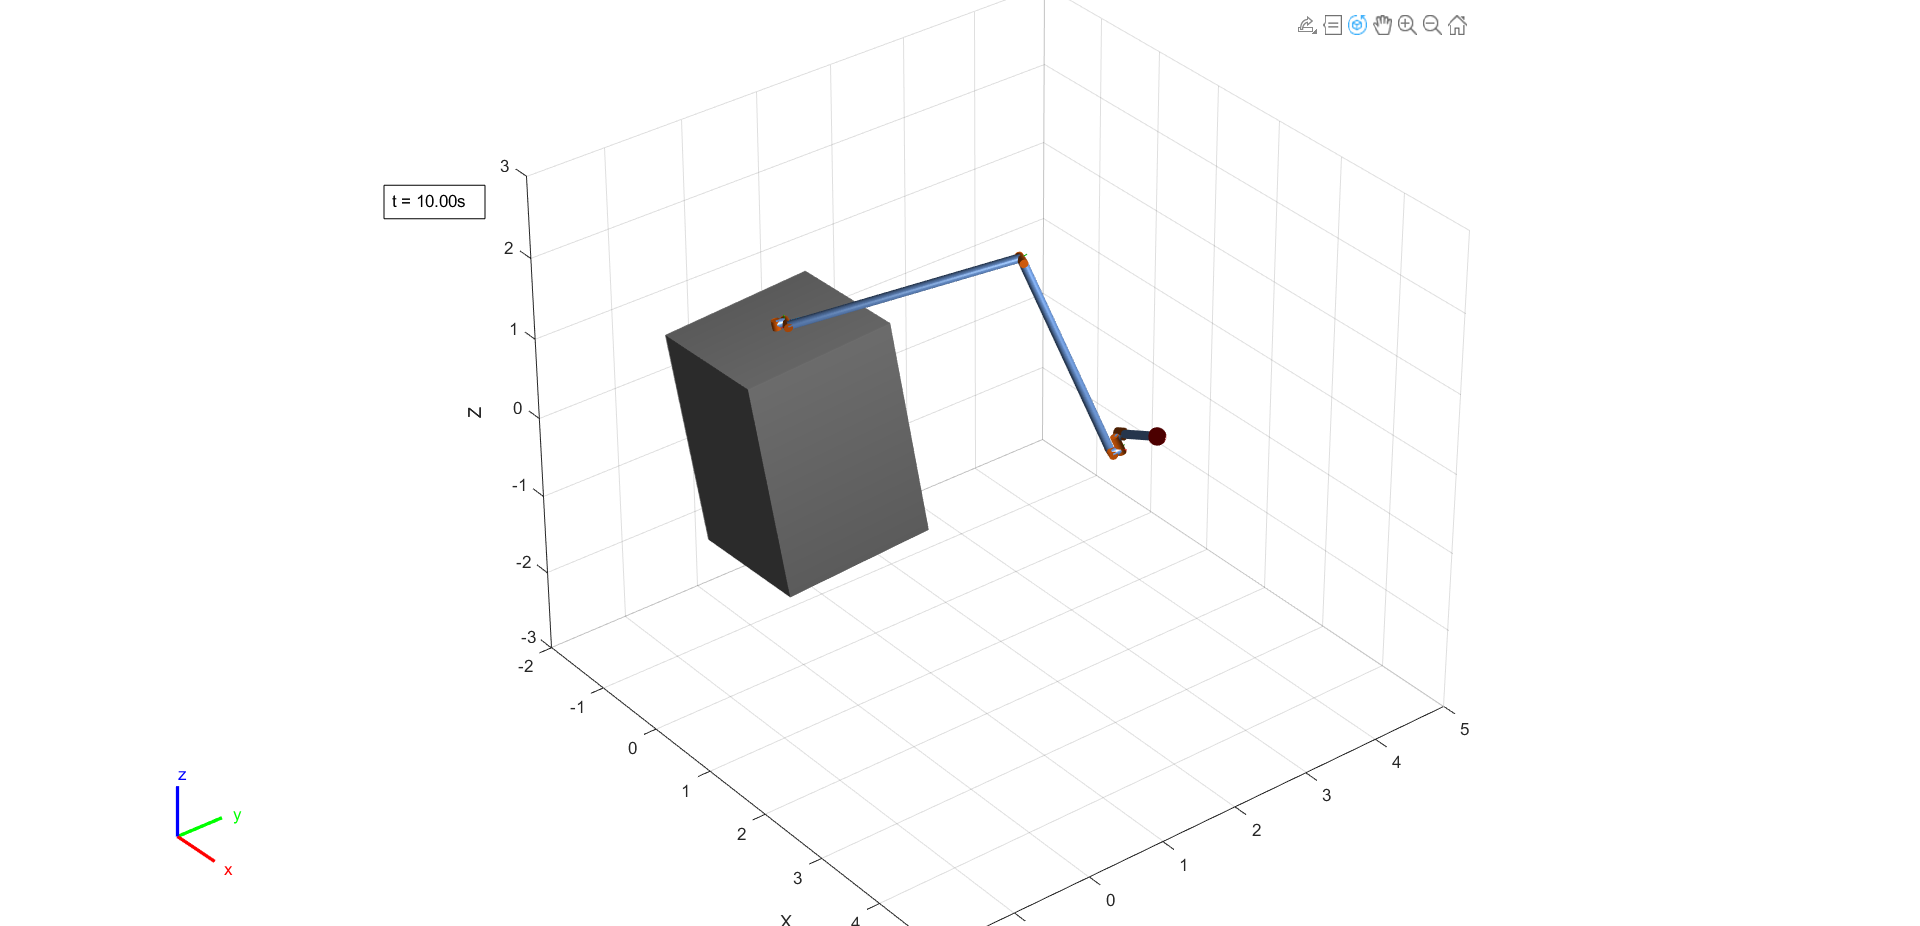

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sr.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc

Elapsed time is 12.553429 seconds.
